# INME 4012 - Project

# Machine Design

## Scenario: 

A punch press is used to stamp circular steel washers from a workpiece. A schematic of the washer producing device is shown below. A flywheel is directly coupled to a crankshaft. An electric motor drives the crankshaft via a gear reducer. As the motor rotates, a punching die reciprocates producing washers each revolution of the crankshaft. The purpose of the flywheel is to reduce the size of the motor and gearbox necessary to produce these washers. The optimal motor speed is 1000-1,100 RPM. The crankshaft diameter is 55 mm and fabricated from ASTM 1018 annealed steel. In order to meet production demands, 100 disks are produced each minute. The crankshaft torque necessary to stamp each washer is shown in a separate figure below. During “punching”, the flywheel speed is reduced and the energy to reduce the flywheel speed is used to “help” produce the washers. The motor increases the speed of the flywheel during the non-punching region. Also shown below is the flywheel speed variation. 

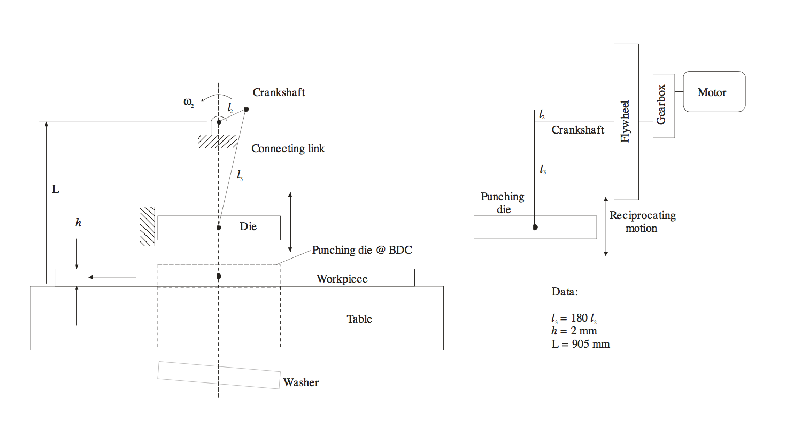

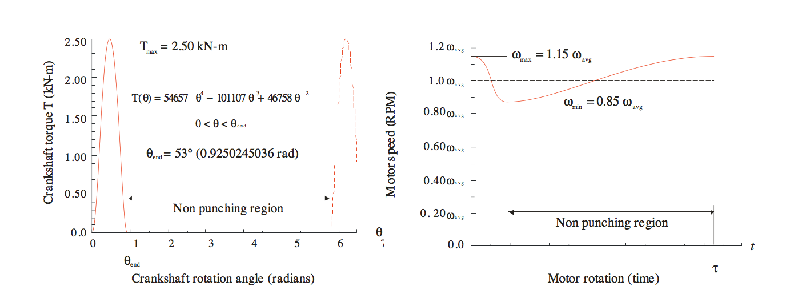

The following information is given:

crankshaftDiameter = 55; % mm
l2 = crankshaftDiameter;
h = 2; % mm
l3 = 180*l2;
L = 905; % mm

The torque can be computed as:

thetaEnd = 53; %deg
fracPress = round(10000*(thetaEnd/360));
fracNoPress = round(10000*((360-thetaEnd)/360));
thetaPress = linspace(0,0.9250245036,fracPress);
torqueEq = @(thetaVar) 54657.*(thetaVar.^4)-101107*(thetaVar.^3)+46758*(thetaVar.^2);
torquePress = torqueEq(thetaPress);
SecondPress = 360-0.5*thetaEnd;
SecondPress = SecondPress*(pi/180);
thetaNoPress = linspace(0.9250245036,SecondPress,fracNoPress+1);
thetaPress2 = linspace(SecondPress,SecondPress+0.9250245036,fracPress);
thetaNoPress2 = linspace(SecondPress+0.9250245036,2*SecondPress,fracNoPress+1);
thetaPress3 = linspace(2*SecondPress,2*SecondPress+0.9250245036,fracPress);
thetaNoPress3 = linspace(2*SecondPress+0.9250245036,3*SecondPress,fracNoPress+1);
thetaPress4 = linspace(3*SecondPress,3*SecondPress+0.9250245036,fracPress);
thetaNoPress4 = linspace(3*SecondPress+0.9250245036,4*SecondPress,fracNoPress+1);
thetaPress5 = linspace(4*SecondPress,4*SecondPress+0.9250245036,fracPress);
thetaNoPress5 = linspace(4*SecondPress+0.9250245036,5*SecondPress,fracNoPress+1);
thetaPress6 = linspace(5*SecondPress,5*SecondPress+0.9250245036,fracPress);

The torque behaves as:

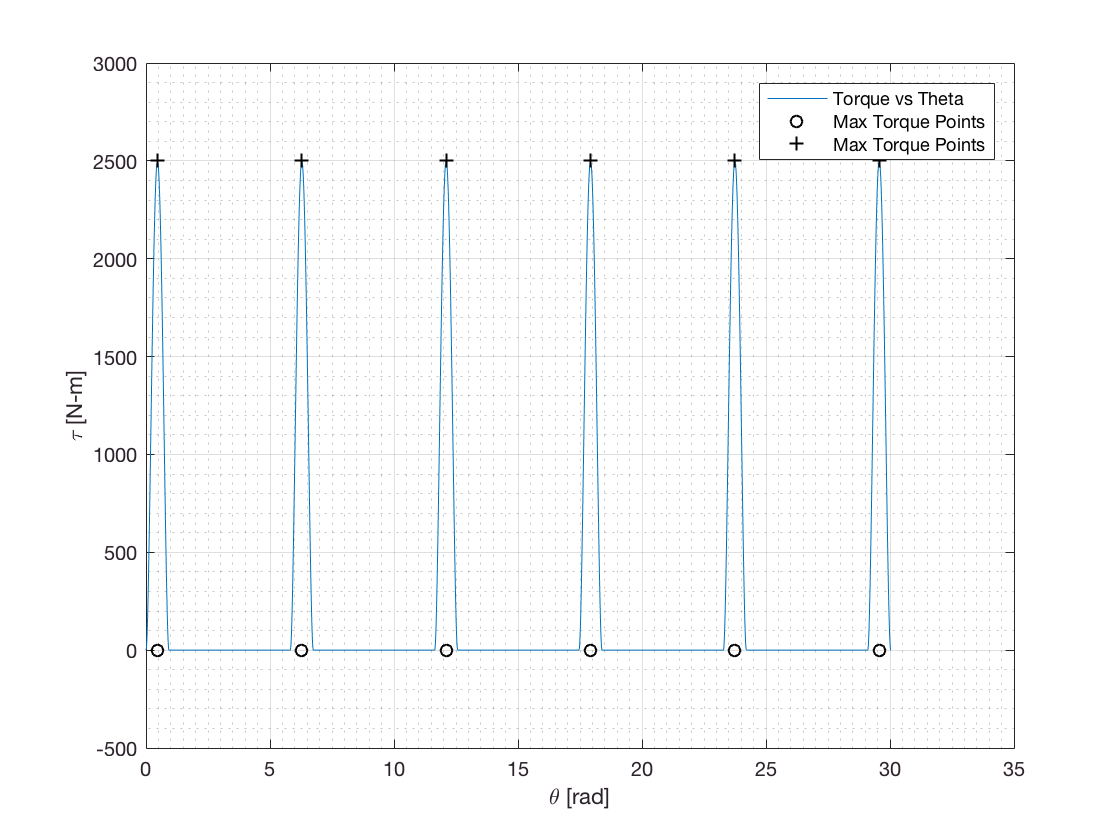

theta = [thetaPress,thetaNoPress,thetaPress2,thetaNoPress2,...
    thetaPress3,thetaNoPress3,thetaPress4,thetaNoPress4,thetaPress5,thetaNoPress5,thetaPress6];
torque = [torquePress,zeros(1,numel(thetaNoPress)),torquePress,...
    zeros(1,numel(thetaNoPress2)),torquePress,zeros(1,numel(thetaNoPress3)),...
    torquePress,zeros(1,numel(thetaNoPress2)),torquePress,zeros(1,numel(thetaNoPress2)),torquePress];
figure('Name','Torque vs Theta')
plot(theta,torque); hold on

scatter([(0.5*0.9250245036),2*pi,4*pi-(0.5*0.9250245036),...
    6*pi-2*(0.5*0.9250245036),8*pi-3*(0.5*0.9250245036),...
    10*pi-4*(0.5*0.9250245036)],[0,0,0,0,0,0],'ko')
scatter([(0.5*0.9250245036),2*pi,4*pi-(0.5*0.9250245036),...
    6*pi-2*(0.5*0.9250245036),8*pi-3*(0.5*0.9250245036),...
    10*pi-4*(0.5*0.9250245036)],[2500,2500,2500,2500,2500,2500],'k+')

legend('Torque vs Theta','Max Torque Points','Max Torque Points')
xlabel('\theta [rad]')
ylabel('\tau [N-m]')
grid on
grid minor

Attempting to determine the punch press' speed, we determine how many radians are required per spike. From this estimate, whose accuracy will increase with more spikes as a cummulative error exists. From the problem statement, we know that 100 disks are required per minute. 

The central point of any spike beyond the third spike can be determined using the following equation:


$$T_{max_{location}}=2(n-1)\pi-(n-2)\left(\frac{53\pi}{360}\right)$$


The rightmost point can be easily determined by adjusting the second term in the previous equation:


$$T_{max_{location}}=2\pi (n-1)-(n-1)\left(\frac{53\pi}{360}\right)\\
T_{max_{location}}=\left(2\pi - \left(\frac{53\pi}{360}\right)\right)(n-1)\\
T_{max_{location}} \approx 5.8207(n-1)$$


From this equation we determine the 100th spike location to be:

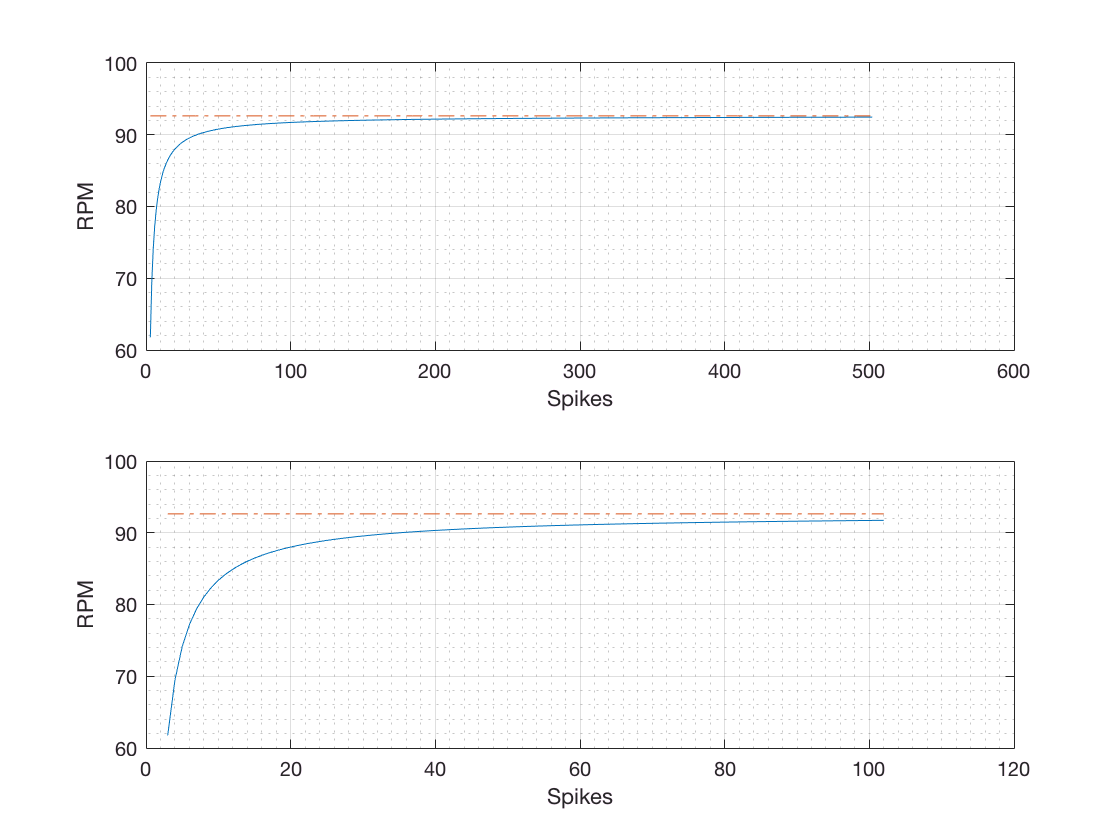

spikes = [3:1000000];
% Here, the full expression is used to facilitate code maintenance.
EstimatedRadians = (2.*(spikes-1).*pi)-((spikes-1).*(0.5*0.9250245036));
EstimatedRevs = EstimatedRadians./(2*pi); % revs
RevsPerSpike = EstimatedRevs./spikes; % revs/spikes
ReqDisks = 100;
RequiredRPMs = RevsPerSpike.*ReqDisks;
figure('Name','EstimatedRevs vs Terms Used')
subplot(2,1,1)
plot(spikes(1:500),RequiredRPMs(1:500)); hold on
plot(spikes(1:500),max(RequiredRPMs).*ones(1,numel(spikes(1:500))),'-.')
xlabel('Spikes')
ylabel('RPM')
grid on 
grid minor
subplot(2,1,2)
plot(spikes(1:100),RequiredRPMs(1:100)); hold on
plot(spikes(1:100),max(RequiredRPMs).*ones(1,numel(spikes(1:100))),'-.')
xlabel('Spikes')
ylabel('RPM')
grid on 
grid minor

As seen from the previous figure, the log-like trend tends asymptotically to a certain limit. However, using 100 spikes yields a reasonable approximation. Given the power of modern computing hardware, we will use a 1M spikes for a smooth approximation.

RequiredRPMs = max(RequiredRPMs)

RequiredRPMs = 92.6388

The required RPM for the punch press' motor are much higher than the one required for the actual pressing mechanism.

MotorRPMs = 1020; % Yields a value near integer for the reduction
GearboxReduction = round(MotorRPMs/RequiredRPMs)

GearboxReduction = 11

Three reductions will be used:

**First Reduction -> 1:2**

**Second Reduction -> 1:2**

**Third Reduction -> 1:2.75 **

**Overall GearBox Reduction -> 1:11**

The reductions are named such that the third reduction is the largest and connected to the motor.

GearNo = 6;
FirstReduction = 2;
SecondReduction = 2;
ThirdReduction = 2.75;

## Building the gearbox

The proposed gearbox has 3 gear pairs. The governing equations are:


$$\frac{N_2}{N_1}=2\\

\frac{N_4}{N_3}=2\\

\frac{N_6}{N_5}=2.75\\ \\

N_1+N_2=N_3+N_4\\
N_3+N_4=N_5+N_6\\
N_1+N_2=N_5+N_6$$


From these equations and some algebraic manipulation,


$${N_2}=2{N_1}\\

{N_4}=2{N_3}\\

{N_6}=2.75{N_5}\\ \\

{N_1}={N_3}\\
{N_3}=1.25{N_5}\\$$


We'll leave these expressions momentarily and move to compute the maximum and minimum angular speeds according to the problem statement. Further, we will compute the required energy (ie work) and consequently the FlyWheel's Inertia.


$$\omega_{ave}=92.64 ~RPM = 9.7 \frac{rad}{s}\\
\omega_{max}=1.15\omega_{ave}=11.155 \frac{rad}{s}\\
\omega_{min}=0.85\omega_{ave}=8.245 \frac{rad}{s}\\$$


The total work done for 6 spikes can be computed numerically (employing the trapezoidal rule) from the previously created arrays as,

work = trapz(theta,torque)/6; % Joules
fprintf('Work to Press: %10.2f J',work)

Work to Press:    1233.23 J

fprintf('Work to Press: %10.2f kJ',work/1000)

Work to Press:       1.23 kJ

The required inertia can be computed as,


$$\frac{2\left(E_2-E_1\right)}{\left(\omega_{max}^2-\omega_{min}^2\right)}=I$$


The change in energy is equaled to the work required per disk,


$$\frac{2(W)}{\left(\omega_{max}^2-\omega_{min}^2\right)}=I$$


omega_ave = (RequiredRPMs*2*pi)/60;
omega_max = 1.15*omega_ave;
omega_min = 0.85*omega_ave;

I = (2*work)/((omega_max^2)-(omega_min^2)); % kg*m^2
fprintf('Flywheel Inertia: %10.2f kg-m^2 \n',I)

Flywheel Inertia:      43.68 kg-m^2 


The chosen flywheel must have this inertia. 

The average torque to press can be computed as:


$$\bar \tau = \frac{trapz(\theta_{press},\tau_{press})}{\theta_{max}}$$


averageTorque = trapz(thetaPress,torquePress)/(0.9250245036);
averageTorqueArray = zeros(1,numel(thetaPress)+2);
averageTorqueArray(2:numel(thetaPress)) = averageTorque;
disp(['Average Torque: ', num2str(averageTorque),' N-m'])

Average Torque: 1333.187 N-m


This result can be superimposed over the actual punch torque as:

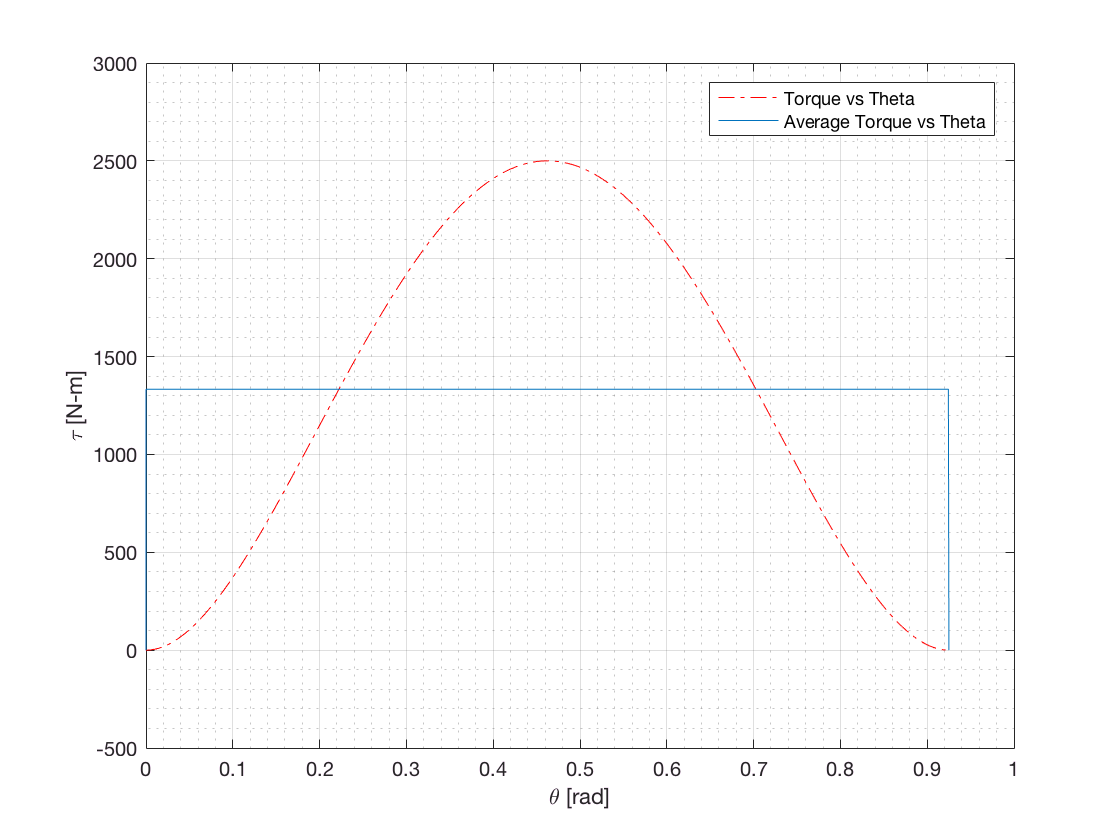

figure('Name','Torque/AverageTorque vs theta')
plot(thetaPress,torquePress,'r-.',[0,thetaPress,0.9250245036],averageTorqueArray)
legend('Torque vs Theta','Average Torque vs Theta')
xlabel('\theta [rad]')
ylabel('\tau [N-m]')
grid on
grid minor

The power transmitted will be approximated using the average torque as,


$$\bar T \omega_{ave} = P$$


Therefor, this linear approximation results in the average power transmitted. However, peak motor power can be estimated by presuming that peak torque occurs at the average angular velocity. 


$$T_{max} \omega_{ave} = P_{peak}$$


Power_ave = averageTorque*omega_ave; disp(['Average Power: ',num2str(Power_ave/1000),' kW']);...
    disp(['Average Power: ',num2str(1.34*Power_ave/1000),' hp']);...
Power_peak = max(torquePress)*omega_ave;...
disp(['Peak Power:    ',num2str(Power_peak/1000),'  kW']);...
disp(['Peak Power:    ',num2str(1.34*Power_peak/1000),'  hp'])

Average Power: 12.9334 kW


Average Power: 17.3308 hp


Peak Power:    24.253  kW


Peak Power:    32.499  hp


As seen, the maximum power draw exceeds the 20 kW while the motor supplies 12.9334 on average. This power is used to store energy in the Flywheel. We presume the FlyWheel is made from Cast Iron. The thickness will be assumed to be 57 mm.


$$\rho = 7800 ~kg/m^3$$


The process will be solved as,


$$m = \frac{\pi d^2 t \rho}{4}\\ \\

I = 43.68 kg-m^2 = \frac{md^2}{8}\\

m*d^2 = 349.44 \\

m = \frac{349.44}{d^2}\\

\frac{\pi d^2 t \rho}{4}=\frac{349.44}{d^2}\\

d = \left(\frac{1397.8}{\pi (57/1000) 7800}\right)^{0.25}$$


th = (57/1000);
cost = 1.42; % USD/kg
rho = 7800;
FlyWheeld = (1397.8/(pi*th*rho))^0.25;
m = (pi*(FlyWheeld^2)*th*rho)/4; 
disp(['d = ', num2str(1000*round(FlyWheeld,2)),' mm']);...
disp(['m = ', num2str(round(m,2)),' kg']);...
disp(['cost = $', num2str(round(m*cost,2))])

d = 1000 mm


m = 349.32 kg


cost = $496.03


In order to visualize the flywheel,

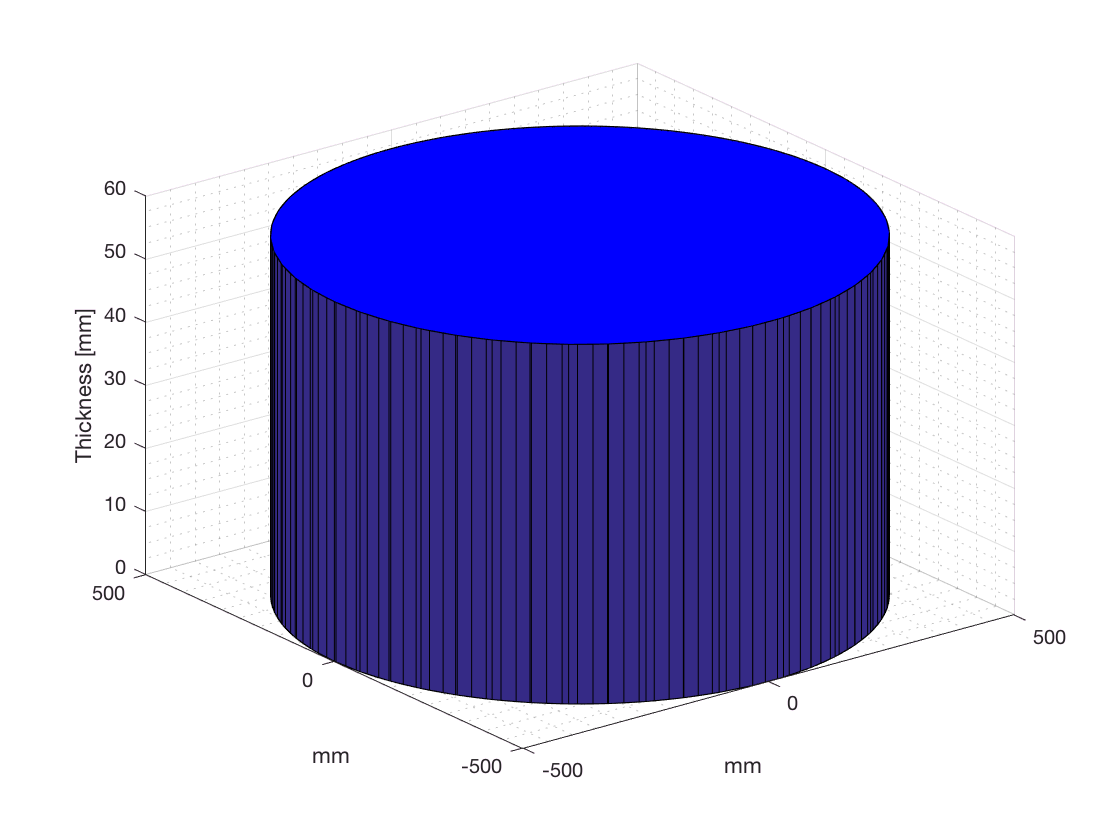

r = round(1000*FlyWheeld^2/2);
h = round(th*1000);
angle = 0:0.05:2*pi;
x = r*cos(angle);
y = r*sin(angle);
y(end) = 0;
z1 = 0;
z2 = h;
[X,Y,Z] = cylinder(1000/2,50);
Z(2,:)=57;
figure('Name','Flywheel')
surf(X,Y,Z); hold on
xlabel('mm')
ylabel('mm')
zlabel('Thickness [mm]')
grid on
grid minor
patch(x,y,z1*ones(size(x)),'b'); hold on
patch(x,y,z2*ones(size(x)),'b'); hold on
surf([x;x],[y;y],[z1*ones(size(x));z2*ones(size(x))]); hold on

## Gear Definition

The gears employed will be Helical Gears. 

The first gear pair (connected to the crankshaft) will be defined as a 17 tooth pinion driving a 34 tooth gear. Th middle pair will be designed to be identical to the first gear pair given the identical reduction. The last reduction will feature a 20 tooth tooth pinion driving a 55 tooth gear. Bringing back the previously worked equations,


$${N_2}=2{N_1}\\

{N_4}=2{N_3}\\

{N_6}=2.75{N_5}\\ \\

{N_1}={N_3}\\
{N_3}=1.25{N_5}\\$$


Following this notation,


$$N_1 = 17\\
N_2 = 34\\
N_3 = 17\\
N_4 = 34\\
N_5 = 20\\
N_6 = 55\\$$


The pitch diameter can be computed by setting the following values for the module,


$$m_6 = 2\\
m_4 = 8\\
m_2 = 10\\$$


From these values, the pitch diameter can be easily obtained as,


$$d_2 = 10*34=340~mm\\
d_1 = d_2/2 = 170~mm\\
d_4 = 34*8 = 272~mm\\
d_3 = d_4/2 = 136~mm\\
d_6 = 2*55 = 110~mm\\
d_5 = d_6/2.75 = 40\\$$


The following modules are computed from the resulting diameters,


$$m_5 = 2 \\
m_3 = 8 \\
m_1 = 10\\$$


N1 = 17; 
N3 = N1; 
N2 = FirstReduction*N1;
N4 = N2;
N5 = 20;
N6 = ThirdReduction*N5;
m6 = 2;
m4 = 8;
m2 = 10;
d2 = m2*N2;
d1 = d2/FirstReduction;
d4 = m4*N4;
d3 = d4/SecondReduction;
d6 = m6*N6;
d5 = d6/ThirdReduction;
m1 = d1/N1;
m3 = d3/N3;
m5 = d5/N5;
P1 = N1/d1;
P2 = N2/d2;
P3 = N3/d3;
P4 = N4/d4;
P5 = N5/d5;
P6 = N6/d6;

These quantities will be vectorized to facilitate future computing,

P = [P1, P2, P3, P4, P5, P6];
m = [m1, m2, m3, m4, m5, m6];
N = [N1, N2, N3, N4, N5, N6]

N =     17    34    17    34    20    55


d = [d1, d2, d3, d4, d5, d6]

d =    170   340   136   272    40   110


The addendum and dedendum can be easily computed through the following relationships for Helical Gears:


$$a = \frac{1.00}{P_n}\\

b = \frac{1.25}{P_n}$$


a = 1.00.*m; % Addendum
b = 1.25.*m; % Dedendum
p = pi./P;   % circular pitch
t = p./2;    % tooth thickness
c = b-a;     % clearance

The helical and pressure will be explicitly labeled to provide a general framework.

helicalAngle = 0;   % Deg
pressureAngle = 20; % Deg
P = P.*cosd(helicalAngle);

m = m.*cosd(helicalAngle);
disp('Pitch Diameter has been generalized to individual gears although gear pairs have the same value.');...
disp(['Pitch Diameter: ',num2str(round(P,4),'%10.5f'),' 1/mm']);... 
    disp(['Pitch Diameter: ',num2str(round(P./0.039,4),'%10.5f'),' 1/in'])

Pitch Diameter has been generalized to individual gears although gear pairs have the same value.\n


Pitch Diameter: 0.10000   0.10000   0.12500   0.12500   0.50000   0.50000 1/mm


Pitch Diameter: 2.56410   2.56410   3.20510   3.20510  12.82050  12.82050 1/in


The pitch diameter can be generalized to:

pitchDiameter = N./P

pitchDiameter =    170   340   136   272    40   110


The base diameter can also be generalized to:

baseDiameter = d.*cosd(pressureAngle)

baseDiameter =   159.7477  319.4955  127.7982  255.5964   37.5877  103.3662


Other relevant quantities include,

- Standard center distance


$$SCD = \frac{D+d}{2}$$


SCD = (d(1:2:6)+d(2:2:6))/2

SCD =    255   204    75


- Outside Diameter


$$OD = D+2a$$


OD = d+2*a

OD =    190   360   152   288    44   114


- Root Diameter


$$RD = D-2b$$


RD = d-2*b

RD =    145   315   116   252    35   105


- Base helix angle


$$\tan^{-1}(\tan(\psi)\cos(\phi))$$


BHA = atand(tand(helicalAngle).*cosd(pressureAngle))

BHA = 0

## Gear Rating

All gear pairs will be evaluated in accordance to the roadmap for the ANSI/AGMA 2001-D04 standard as provided by [Shigley]. 

The first step computes the pitch diameter which has been stored in `pitchDiameter`. The tangential velocity is then computed as,


$$V = {\pi d_p n_p}$$


n = [RequiredRPMs,RequiredRPMs.*2,RequiredRPMs.*2,...
(RequiredRPMs.*2).*2,(RequiredRPMs.*2).*2,((RequiredRPMs.*2).*2).*2.75]; % RPM
V = ((pi.*pitchDiameter.*n)./1000)./60 % m/s 

V =     0.8246    3.2984    1.3194    5.2774    0.7761    5.8692


The transmitted load can then be computed through the following expression,


$$W^t[N]=\frac{Power [Watts]}{V[m/s]}$$


W_t = Power_ave./V % Newton

W_t =    1.0e+04 *

    1.5685    0.3921    0.9803    0.2451    1.6665    0.2204


The **Overload Factor**,$K_o$, can be obtained from the following table:

PowerSource = {'Uniform    ';'LightShock ';'MediumShock'};
Uniform = [1.00; 1.25; 1.50];
ModerateShock = [1.25; 1.50; 1.75];
HeavyShock = [1.75; 2.00; 2.25];
KoTable = table(PowerSource,Uniform,ModerateShock,HeavyShock);
disp('                 Table of Overload Facots, Ko               ');...
disp('------------------------------------------------------------');...
disp('                        Driven Machine                      ');...
disp('------------------------------------------------------------');...
disp(KoTable)

                 Table of Overload Facots, Ko               


------------------------------------------------------------


                        Driven Machine                      


------------------------------------------------------------


     PowerSource     Uniform    ModerateShock    HeavyShock
    _____________    _______    _____________    __________

    'Uniform    '       1       1.25             1.75      
    'LightShock '    1.25        1.5                2      
    'MediumShock'     1.5       1.75             2.25      



From the problem statement and the derivation made upto this point, we can model the engine as a light shock power source to a moderate shock machine which yields a $K_o$** of 1.50**.

The **Dynamic Facor**, $ K_v$, can be obtained from the following equation,


$$K_v = \left(\frac{A+\sqrt{200V}}{A}\right)^B$$


where,


$$A = 50+56(1-B)\\
B = 0.25(12-Q_v)^{2/3}\\
\\
A = 50+56\left(1-\left( 0.25(12-Q_v)^{2/3} \right)\right)$$


And $Q_v$ is defined as the set of quality number ranging usually from 3 to 7 for commercial applications and between 8 and 12 for precision gearing. 

Qv = 5;
B = 0.25*((12-Qv)^(2/3));
A = 50 + 56*(1-B);
% The following callback asserts the validity of the selected Qv.
assert(min(((A+(Qv-3)^2)/200) < V),'Please change Quality number as V exceeds the recommended maximum.')

Kv = ((A+sqrt(200.*V))./A).^B

Kv =     1.2125    1.4216    1.2682    1.5312    1.2062    1.5597


The **Size Factor**, $ K_s$, can be obtained from the following equation,


$$K_s = 1.192 \left(\frac{F\sqrt{Y}}{P}\right)^{0.0535}$$


Y = [0.303,0.371,0.303,0.371,0.322,(0.409+0.422)/2];
F = 50; disp(['Face Width: ',num2str(F,'%15.2f'), ' mm']); disp(['Face Width:  ',num2str(0.039*F,'%15.2f'), ' in'])

Face Width: 50.00 mm
Face Width:  1.95 in


Ks = 1.192*(((F.*sqrt(Y))./P).^0.0535)

Ks =     1.6099    1.6186    1.5908    1.5994    1.4795    1.4896


When working in SI units, the **Load-Distribution Factor** is denoted as $ K_H$ and is determined through:


$$K_H = C_{mf} =1+C_{mc}(C_{pf}C_{pm}+C_{ma}C_{e})$$


In this expression,


$$\frac{F}{d_p} ~≤~2$$


assert(min(F./pitchDiameter <= 2),'Condition for this procedure not met!') 

In order to compute the necessary procedure, several logical decisions must be made,

- Crowned or Uncrowned

Crowned = 1; % Mark 1 if crowned, 0 otherwise;
Cmc = zeros(1,round(numel(N)));
if Crowned == 1
    Cmc(:) = 1;
else
    Cmc(:) = 0.8;
end

- Determine $C_{pf}$ from the dedendum and pitch diameter.

Cpf = zeros(1,round(numel(N)));
bMask = b;
b10d = (bMask./(10.*pitchDiameter));

if any(b10d < 0.05)
    b10d(b10d < 0.05) = 0.05;
end

logicalPath = bMask <= 25;
if any(logicalPath)
    Cpf(logicalPath) = b10d(logicalPath) - 0.025;
end

logicalPath = b > 25 & b <= 425;
if any(logicalPath)
    Cpf(logicalPath) = b10d(logicalPath) - 0.0375+4.92*(10^-4).*bMask(logicalPath);
end

logicalPath = b > 425 & b <= 1000;
if any(logicalPath)
    Cpf(logicalPath) = b10d(logicalPath) - 0.1109 + 8.15*(10^-4).*bMask(logicalPath) - 3.53*(10^-7).*(bMask(logicalPath).^2);
end
Cpf

Cpf =     0.0250    0.0250    0.0250    0.0250    0.0250    0.0250


- For immediatly adjacent bearings, $C_{pm} =1$. Otherwise, $C_{pm} =1.1$.

AdjacentBearing = 1;
Cpm = zeros(1,round(numel(N)));
if AdjacentBearing == 1
    Cpm(:) = 1;
else
    Cpm(:) = 1.1;
end
Cpm

Cpm =      1     1     1     1     1     1


- The mesh alignment factor, $C_{ma}$


$$C_{ma}=A+BF+CF^2$$


                        The conditions must be selected according to the following numeric IDs:

-         Open Gearing

-         Commercial, enclosed units

-         Precision, enclosed units

-         Extraprecision, enclosed gear units

Cma = zeros(1,round(numel(N)));
CmaConditions = 2; % Match CmaConditions with the numeric IDs

CmaFact = [0.247, 0.0167, -0.765*(10^-4); 0.127, 0.0158, -0.930*(10^-4);...
    0.0675, 0.0128, -0.926*(10^-4); 0.00360, 0.0102, -0.822*(10^-4)];
Cma(:) = CmaFact(CmaConditions,1) + CmaFact(CmaConditions,2)*F + CmaFact(CmaConditions,3)*(F^2)

Cma =     0.6845    0.6845    0.6845    0.6845    0.6845    0.6845


- The mesh alignment correction factor, $C_{e}$

-                     For gearing adjusted at assembly, or compatibility is improved by lapping, or both: $C_{e}=0.8$

-                     For all other conditions: $C_{e}= 1.0$

CeConditions = 2;
Ce = zeros(1,round(numel(N)));
if CeConditions == 2
    Ce(:) = 1.0;
else
    Ce(:) = 0.8;
end
Ce

Ce =      1     1     1     1     1     1


We can now compute $ K_H$,


$$K_H = C_{mf} =1+C_{mc}(C_{pf}C_{pm}+C_{ma}C_{e})$$


Kh = 1 + Cmc.*((Cpf.*Cpm)+(Cma.*Ce))

Kh =     1.7095    1.7095    1.7095    1.7095    1.7095    1.7095


We must now compute the **Stress-Cycle Factors**, $Y_N ~\&~  Z_N$,


$$m_G = \frac{N_G}{N_P}$$



$$(Y_N)_P = \frac{1.3558N^{-0.0178} + 1.6831N^{-0.0323}}{2}$$



$$(Z_N)_P = \frac{1.4488N^{-0.0230} + 2.4660N^{-0.0560}}{2}$$



$$(Y_N)_G = \frac{1.3558 \left(\frac{N}{m_G}\right) ^{-0.0178} + 1.6831 \left(\frac{N}{m_G}\right)^{-0.0323}}{2}$$



$$(Z_N)_G = \frac{1.4488 \left(\frac{N}{m_G}\right) ^{-0.0230} + 2.4660 \left(\frac{N}{m_G}\right) ^{-0.0560}}{2}$$


mG = N(2:2:6)./...
     N(1:2:6);
YNP = zeros(1,numel(N));
YNG = zeros(1,numel(N));
ZNP = zeros(1,numel(N));
ZNG = zeros(1,numel(N));

life = 10^9;
lifemg = life ./ mG;

YNP(:) = ((1.3558.*life.^(-0.0178))+(1.4488.*life.^(-0.0323)))/2;
ZNP(:) = ((1.4488.*life.^(-0.0230))+(2.4660.*life.^(-0.0560)))/2;

YNG(1:2) = ((1.3558.*lifemg(1).^(-0.0178))+(1.4488.*lifemg(1).^(-0.0323)))/2;
ZNG(1:2) = ((1.4488.*lifemg(1).^(-0.0230))+(2.4660.*lifemg(1).^(-0.0560)))/2;
YNG(3:4) = ((1.3558.*lifemg(2).^(-0.0178))+(1.4488.*lifemg(2).^(-0.0323)))/2;
ZNG(3:4) = ((1.4488.*lifemg(2).^(-0.0230))+(2.4660.*lifemg(2).^(-0.0560)))/2;
YNG(5:6) = ((1.3558.*lifemg(3).^(-0.0178))+(1.4488.*lifemg(3).^(-0.0323)))/2;
ZNG(5:6) = ((1.4488.*lifemg(3).^(-0.0230))+(2.4660.*lifemg(3).^(-0.0560)))/2;

disp(table(YNP',YNG',ZNP',ZNG','VariableNames',{'YN_P','YN_G','ZN_P','ZN_G'}))

     YN_P       YN_G       ZN_P       ZN_G  
    _______    _______    _______    _______

    0.83969    0.85391    0.83609    0.85861
    0.83969    0.85391    0.83609    0.85861
    0.83969    0.85391    0.83609    0.85861
    0.83969    0.85391    0.83609    0.85861
    0.83969    0.86053    0.83609     0.8692
    0.83969    0.86053    0.83609     0.8692



Now, let's compute the **Reliability Factor** $K_R$ ($Y_Z$),


$$K_R = 0.50-0.109 \ln{(1-R)}~~~~~0.99~≤~R~≤~0.9999$$


R = 0.999;
KR = zeros(1,numel(N));
KR(:) = 0.50 - 0.109*log(1-R)

KR =     1.2529    1.2529    1.2529    1.2529    1.2529    1.2529


The **Temperature Facto****r** $K_T$ can be equaled to 1 for this application.

KT = ones(1,numel(N))

KT =      1     1     1     1     1     1


A factor denoted as **R****im-Thickness Factor** $K_B$ can also be setted to 1 assuming constant thickness gears.

RB = ones(1,numel(N))

RB =      1     1     1     1     1     1


The pinion and gear **Bending-Strength Geometry Factor** $J$ is estimated from *Figure 14-6* and must be updated if the number of tooths is changed. 

J1 = 0.295;
J2 = 0.370;
J3 = 0.295;
J4 = 0.370;
J5 = 0.330;
J6 = 0.405;
%---------------------------%
J = [J1, J2, J3, J4, J5, J6];

The **Surface-Strength Geometry Factor** $I$ (also called the *pitting-resistance geometry factor*) can be easily computed by setting $m_n$ to 1 and evaluating the following expression:


$$I = \left(\frac{\cos(\phi)\sin(\phi)}{2m_n}  \right) \left(\frac{m_G}{m_G+1}  \right)$$


mn = 1; % which is valid for spur gears
I_3 = ((cosd(pressureAngle)*sind(pressureAngle))/2*mn).*(mG./(mG+1));
I = zeros(1,numel(N));
I(1:2) = I_3(1);
I(3:4) = I_3(2);
I(5:6) = I_3(3);
clearvars I_3
I

I =     0.1071    0.1071    0.1071    0.1071    0.1178    0.1178
